# CMSDataAnalysis.mlx

This code reads dilepton files from CMS, plots some kinematic variables, and fits bumps in dilepton mass distributions. The data are available at  [http://opendata.cern.ch/](http://opendata.cern.ch/).

Author: Duncan Carlsmith, UW-Madison

## Initialize 

clear all;% clear variables
delete(findall(0,'Type','figure'))% close all open figure windows

## Import data

Read in csv file downloaded from [http://opendata.cern.ch/.](http://opendata.cern.ch/.) The file must be in the same folder as this script or on your MATLAB path. 

Comment out all but one read line below to select one file. Note that the number of bins for histograms `nbins` defined in the line  is different for small and large data samples. In the `csvread`, we skip the first row of column labels. Also, we skip the first column (event type) for the dimuon files. (The event type column doesn't exist in dielectron file). The first column is then the run number for both types of files.

filename='Zmumu.csv';A=csvread(filename,1,1);nbins=100;
%filename='dimuon.csv';A=csvread(filename,1,1);nbins=3000;
%filename='dielectron.csv';A=csvread(filename,1,0);nbins=3000;
filename ; %drop filename to command window for users benefit

## Convert the resulting array A to vectors

Event number, a proxy for time in case on is interested. or to go use an ig file at CERNOPENdata to display the event.

Event=A(:,2);

Extract vectors of energy, momentum components, transverse momentum (perpendicuar to Z is along the beamline), (pseudo)rapidity, azimuthal angle, charge in units of proton charge, for each of two oppositely charged leptons.

E1=A(:,3);px1=A(:,4);py1=A(:,5);pz1=A(:,6);pt1=A(:,7);
eta1=A(:,8);phi1=A(:,9);q1=A(:,10);
E2=A(:,11);px2=A(:,12);py2=A(:,13);pz2=A(:,14);pt2=A(:,15);
eta2=A(:,16);phi2=A(:,17);q2=A(:,18);
M=A(:,19); %pair mass supplied by CMS

**Reality check**

One would hope the lepton energies and momenta were consistent with the lepton masses. Let's take a look. Compute invariant mass of each lepton and plot the results.

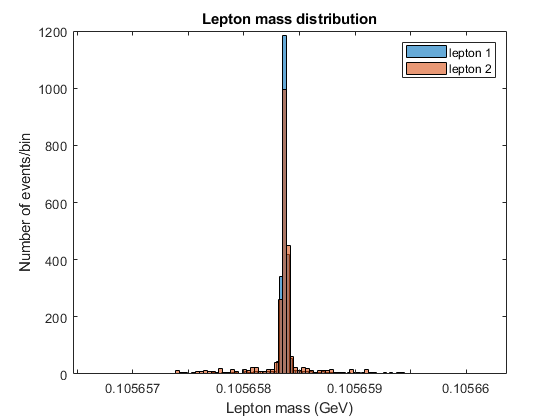

m1= (abs(E1.^2-px1.^2-py1.^2-pz1.^2)).^(1/2);% mass of lepton 1
m2= (abs(E2.^2-px2.^2-py2.^2-pz2.^2)).^(1/2);% mass of lepton 2
h=histogram(m1,nbins);
hold on
h=histogram(m2,nbins);
title('Lepton mass distribution')
xlabel('Lepton mass (GeV)')
ylabel('Number of events/bin')
legend('lepton 1','lepton 2')

The distribution of lepton mass computed from lepton energy and momentum has tails! Hmm. Let's compute the invariant mass of the lepton pairs by summing the energies and momenum components, plot the results and compare to the pair mass supplied by CMS in the data file.

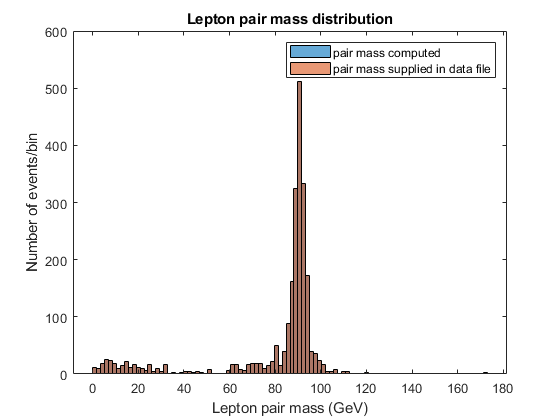

figure;% start a new figure
m3=(abs((E1+E2).^2-(px1+px2).^2-(py1+py2).^2-(pz1+pz2).^2)).^(1/2);
h=histogram(m3,nbins);
hold on
h=histogram(M,nbins);%superpose the mass supplied by CMS
title('Lepton pair mass distribution')
xlabel('Lepton pair mass (GeV)')
ylabel('Number of events/bin')
legend('pair mass computed','pair mass supplied in data file')
hold off

CMS-supplied mass appears roughly consistent with that calculated directly from momenta.

Lepton mass distribution for either muon has a tail; Why is this? Could it concern poor tracking resolution at small polar angle?

Let's look at lepton  mass versus polar angle/rapidity.

figure
scatter(m1,eta1);
hold on
scatter(m2, eta2);
hold off
title('Lepton mass versus rapidity')
xlabel('Lepton mass (GeV)')
ylabel('Lepton rapidity (dimensionless)')

We see the leptons are concentrated at the larger absolute rapidity, i.e. in the forward and backward directions and the tails appear in these regions following the leptons. There is no obvious single place in the detector resulting in the poor lepton momenta or energy and hence mass.

BTW, are the leptons near each other in polar angle or not? Let''s plot the correlation between rapidities event by event.

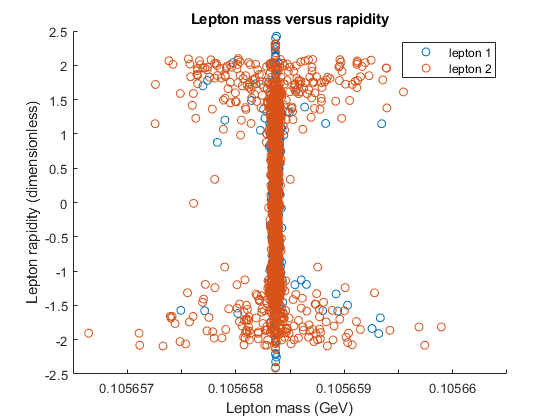

legend('lepton 1','lepton 2')

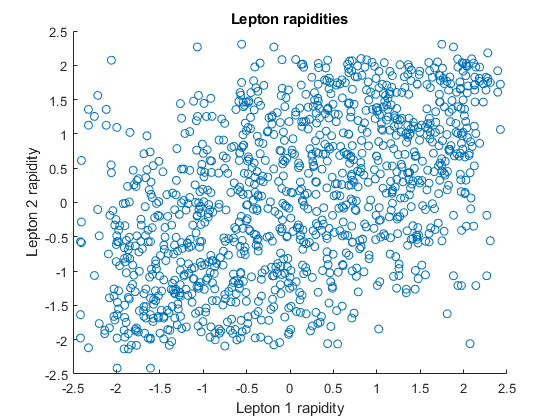

figure
scatter(eta1,eta2);
title('Lepton rapidities')
xlabel('Lepton 1 rapidity')
ylabel('Lepton 2 rapidity')

It appears the leptons tend to be either both forward or both backward.

Maybe lepton mass tails are related to difficulty in measuring momentum or to the precision E and p are recorded in the file.

Let's look at mass versus energy...

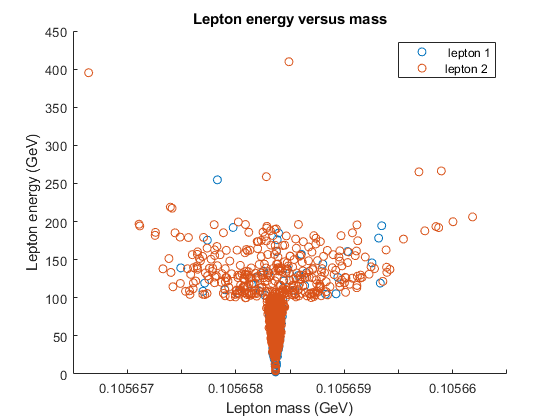

figure
scatter(m1,E1);
hold on
scatter(m2,E2);
title('Lepton energy versus mass')
xlabel('Lepton mass (GeV)')
ylabel('Lepton energy (GeV)')
legend(' lepton 1', 'lepton 2')
hold off

Ah-hah! The lepton mass computed from energy and momentum are wonky at the level of the muon mass (0.1 GeV) for energies above 10 GeV. This probably matters not to the calculation of pair mass for high pair mass but, just in case, let's do a few more checks and compare the pair mass distributions with and without cutting high energy muons.

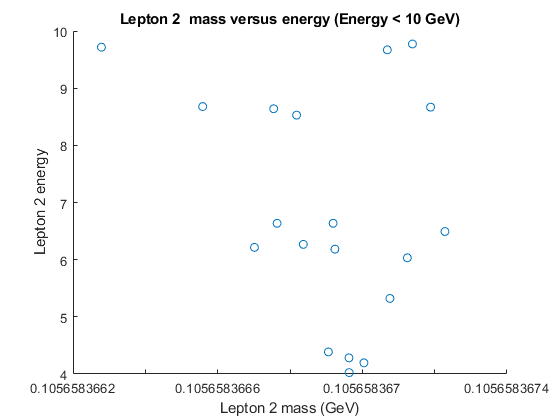

figure
E2flag= (E2<10.);% make vector of booleans for E2's smaller than 10 GeV
E2cut = E2(E2flag);% make vector of energies for E2's smaller than 10 GeV
m2cut=m2(E2flag);% make vector of 2nd lepton mass for E2<10 GeV
scatter(m2cut,E2cut);% plot to see if this worked
title('Lepton 2  mass versus energy (Energy < 10 GeV)')
xlabel('Lepton 2 mass (GeV)')
ylabel('Lepton 2 energy')

E1flag= (E1<10.);% make vector of booleans (logical T or F)
% select mass vector of elements satisfying energy cut on both leptons
m3cut=m3(E1flag & E2flag);
% Compare mass distributions with and without cuts on both lepton energies.
figure
histogram(m3,nbins);
hold on
histogram(m3cut,nbins);
title('Lepton mass distribution nocuts and (E1<10 GeV &E2<10 GeV)')
xlabel('Lepton mass (GeV)')
ylabel('Number of events per bin')
legend('all events','E1<10 GeV &E2<10 GeV ')
hold on

Illustrate how to calculate and plot error bars for histograms using `histcounts` to extract from the histogram the number of events in each bin. The returned vector `Nevents` is  number of entries per bin created by the `histogram` command. `edges` is a vector of bin edges.

[Nevents,edges] = histcounts(m3,nbins);

Compute vector containing statistical standard error in each bin equal to the square root of the number of events in that bin, i.e. assume Poisson statistics.

err=Nevents.^(1/2);

`edges` starts at lower edge of first bin, and ends at upper edge of last bin. Make `mass`=vector of bin centers by eliminating last edge and adding a half bin size to each element.

mass=edges(1:end-1);
mass=mass +(edges(2)-edges(1))/2;

Superpose errorbars on histogram with no connecting lines ('d' option). The vector `mass`, unlike `edges`, has the same length as Nevents.

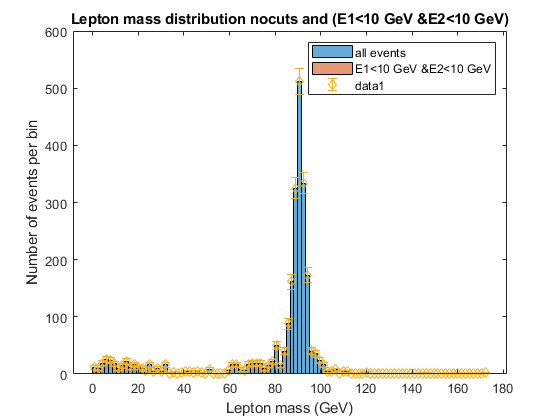

errorbar(mass,Nevents,err,'d');

The mass distributions have similar shapes. If we scaled the distributions to correponds to the same total number of events, they would likely agree within errors bin by bin.

## Mass distribution fit

Perform fit to mass peak near 3 GeV with quadratic background+Gaussian. For high stats sample, one must zoom in to view result since data extend to high masses and quadratic fit extrapolation is wild ouside fit window.

The following fit code was created using the curve fitting tool (found under apps) interactively. Try it yourself. The data selected for fitting in the tool was X data =mass, Y data =Nevents, Weights=err. A custom equation was selected from the fit dropdown (be sure to select topmost option) and then entered in by hand: a1+a2*x +a3*x^2 +c1*exp(-(x-c2)^2/(2*s^2)). The fit coefficients define a quadratic ploynomial + a gaussian. The fit must be restricted to the region near the peak. Use tools drop down and select tools fit by rule. The allowable peak location c2 must be constrained or the nonlinear regression can go find a negative gaussian to represent some little valley in the data. Use fit options and click on the limits for each parameter to constrain. The default parameter limits of -infty and +infty will give nonsensical results.

After fitting, under File, select Generate code to save as a function.

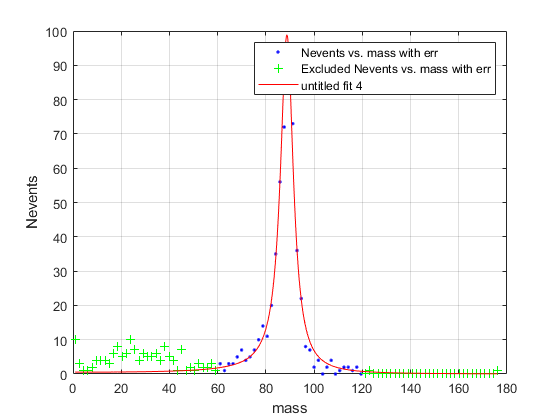

ans =      General model:
     ans(x) = k * 1/((x^2 -  mz^2)^2 + mz^2 * wz^2)
     Coefficients (with 95% confidence bounds):
       k =   3.302e+07  (1.209e+07, 5.395e+07)
       mz =       88.72  (87.94, 89.5)
       wz =      -6.512  (-9.019, -4.006)

createFitVogelZee(mass, Nevents, err)

The fit looks reasonable. The fit value for the center of the peak (parameter c2) is about 3.1 GeV.

Here is another fit for a bump at high mass. It will fail if there are too few events.

% createFit2(mass, Nevents, err)